# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 허찬 **

**학번**** : 201716050    **

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

% 4 points DFT magnitude and phase 

x = [1,2,2,1];
N = 4; X = dft(x,N);
magX = abs(X), phaX = angle(X)*180/pi

magX =     6.0000    1.4142    0.0000    1.4142


phaX =          0 -135.0000  -90.0000  135.0000


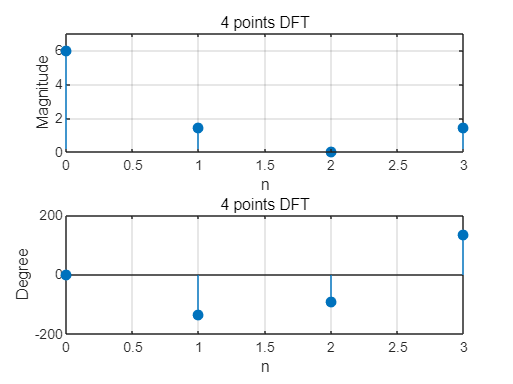

n = [0:1:3]; 

subplot (2,1,1);
stem(n,magX,'filled'); title('4 points DFT');grid on;
xlim([0 3]); xticks("auto");
ylim([0 7]); yticks("auto");
xlabel('n'); ylabel('Magnitude');

subplot (2,1,2); stem(n,phaX,'filled'); 
xlim([0 3]);
ylim([-200 200]);
xlabel('n'); ylabel('Degree'); title('4 points DFT');grid on;

% 4 points IDFT magnitude and phase

x = [1,2,2,1]; N = 4; X = idft(x,N);
magX = abs(X), phaX = angle(X)*180/pi

magX =     1.5000    0.3536    0.0000    0.3536


phaX =          0  135.0000   90.0000 -135.0000


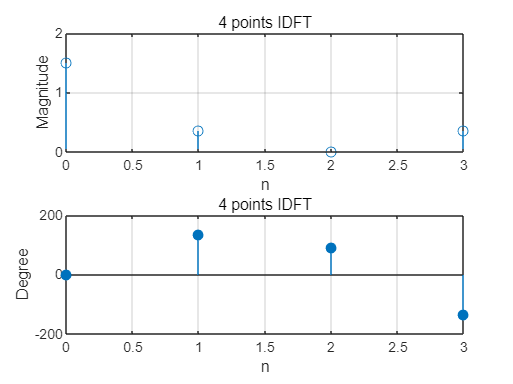

n = [0:1:3];

subplot (2,1,1); 
stem(n,magX,'filled'); title('4 points IDFT');grid on;
xlim([0 3]); xticks("auto");
ylim([0 2]); yticks("auto");
xlabel('n'); ylabel('Magnitude');

subplot (2,1,2); stem(n,phaX,'filled'); 
xlabel('n'); ylabel('Degrees'); title('4 points IDFT');grid on;

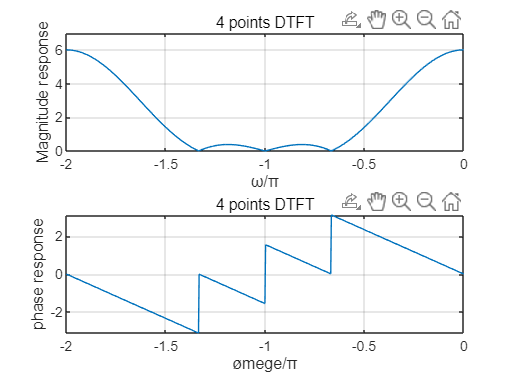

% 4 points DTFT 

x = [1,2,2,1]; 
w = -2*pi:0.01:0;
h = freqz(x,1,w);
% h = freqz(___,w) returns the frequency response vector, h
subplot(2,1,1)
plot (w/pi,abs(h)); 
ylim([0 7]);
title('4 points DTFT'); grid on;
xlabel('\omega/\pi'); ylabel('Magnitude response');

subplot(2,1,2)
plot (w/pi,angle(h));
title('4 points DTFT'); grid on;
xlabel('\omege/\pi'); ylabel('phase response');

DFT의 결과를 DTFT와 비교하라. 

4점 DFT spectrum을 보면 n=0 ~ n=3인구간과

DTFT spectrum w/pi = -2 에서 w/pi가 약 0.5인 구간을 보면 비슷한 양상을 보이는것을 

알 수 있다. 다만 샘플링갯수가 너무 적기 때문에 비교하기 힘들다.

따라서 샘플링갯수를 더 확보해서 늘리거나 zero padding(아래 16점 DFT처럼)을 하는 방법이 있는데 

zero padding을 하는경우에는 고밀도 스펙트럼은 만들 수 있지만 고분해능 스펙트럼은 만들 수 없다는 한계가 있다. 

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

% 16 points DFT
x = [1,2,2,1, zeros(1,12)]; N = 16; X = dft(x,N);
magX = abs(X), phaX = angle(X)*180/pi

magX =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


phaX =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500


n = [0:1:15]; 

subplot (2,1,1);
stem(n,magX,'filled'); title('16 points DFT');grid on;
xlim([0 15]); xticks("auto");
xlabel('n'); ylabel('Magnitude');

subplot (2,1,2); stem(n,phaX,'filled'); 2

ans = 2

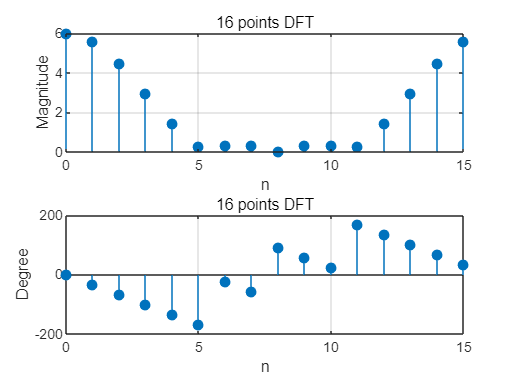

xlim([0 15]);
xlabel('n'); ylabel('Degree'); title('16 points DFT');grid on;

% 16 points IDFT
x = [1,2,2,1, zeros(1,12)]; N = 16; X = idft(x,N);
magX = abs(X), phaX = angle(X)*180/pi

magX =     0.3750    0.3491    0.2788    0.1835    0.0884    0.0163    0.0198    0.0207    0.0000    0.0207    0.0198    0.0163    0.0884    0.1835    0.2788    0.3491


phaX =          0   33.7500   67.5000  101.2500  135.0000  168.7500   22.5000   56.2500  -90.0000  -56.2500  -22.5000 -168.7500 -135.0000 -101.2500  -67.5000  -33.7500


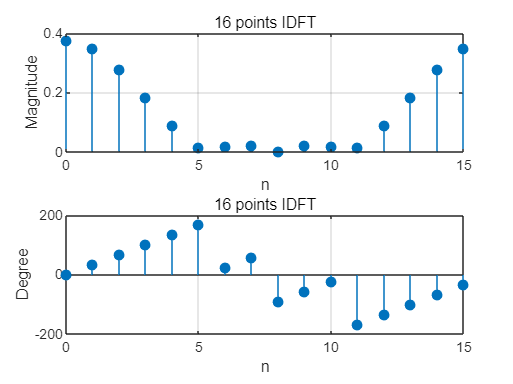

n = [0:1:15];

subplot (2,1,1); 
stem(n,magX,'filled'); title('16 points IDFT');grid on;
xlim([0 15]); xticks("auto");
xlabel('n'); ylabel('Magnitude');

subplot (2,1,2); stem(n,phaX,'filled'); 
xlabel('n'); ylabel('Degree'); title('16 points IDFT');grid on;

2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

xtilde1 = [4,1,-1,1]; N = 4; Xtilde1 = dfs(xtilde1, N)

Xtilde1 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

xtilde2 = [1,0,-1,-1,0]; N = 5; Xtilde2 = dfs(xtilde2, N)

Xtilde2 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\mathrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \mathrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

n = 0:100;
xn = sinc((n-50)/2).^2; 
N = length(xn); % given signal x(n)
Xk = dft(xn,N); 
k = 0:N-1; % DFT of x(n)
mag_Xk = abs(Xk); pha_Xk = angle(Xk)*180/pi; % Mag and Phase of X(k)

subplot(2,1,1); Hs1 = stem(k,mag_Xk,'filled'); 
set(Hs1,'markersize',2);
xlabel('k'); ylabel('Magnitude');
title('Magnitude plots of DFT and DTFT'); hold on

subplot(2,1,2); Hs2 = stem(k,pha_Xk,'filled');
set(Hs2, 'MarkerSize',3); 
xlabel('k'); ylabel('Degrees');
title('Phase plots of DFT and DTFT'); hold on

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

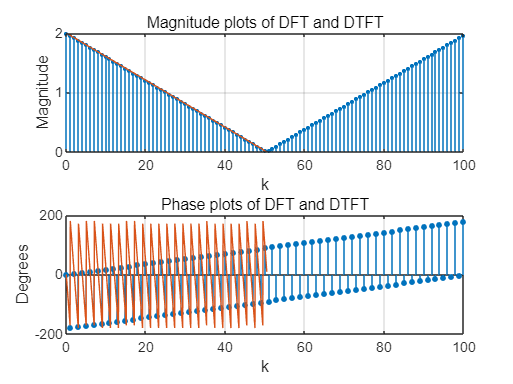

[X,w] = freqz(xn,1,1000); % DTFT of xn
mag_X = abs(X); pha_X = angle(X)*180/pi; % mag and phase of DTFT
Dw = (2*pi)/N; % frequency resolution

subplot(2,1,1); plot(w/Dw,mag_X); grid
hold off
subplot(2,1,2); plot(w/Dw,pha_X); grid
hold off

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

합친 Spectrum결과를 보면 DFT가 DTFT($X\left(e^{j\omega } \right)$)의 sampling된 값이 맞다는걸 확인할 수 있다.

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있다. 단 조건이 필요하다 

x(n)이 유한신호이고, sample의 갯수가 x(n)신호의 크기보다 같거나 커야한다는 조건이다. 

재구성에 필요한 보간 공식은 

$X\left(e^{j\omega } \right)$ = $\sum_{k=0}^{N-1} X\left(k\right)\phi \left(\omega -\frac{2\pi k}{N}\right)$, $\phi \left(\omega \right)=e^{-j\frac{\omega \left(N-1\right)}{2}} \frac{\sin \left(\frac{\omega N}{2}\right)}{\mathrm{Nsin}\left(\frac{\omega }{2}\right)}$이다.

function [Xk] = dft(xn,N)
% Computes Discrete Fourier Transform, N = Length of DFT
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [xn] = idft(Xk,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end

function[Xk] = dfs(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end
